# Graph Connectivity Analysis

### Read Data Model

data=ReadDataModel('cgam_model.xlsx');
N=data.NrOfProcesses;
res=ExergyAnalysis(data);
tfp=res.Info.TableFP;
names=res.Info.ps.ProcessKeys;
showResults(res,'tfp');


FP Table (MW) - REF

 Key            COMB        CMP        TRB        APH       HRSG       STCK        ENV      Total
——————————————————————————————————————————————————————————————————————————————————————————————————
 COMB          0.000      0.000     63.720     24.026     12.662      2.122      0.000    102.530
 CMP          28.651      0.000      0.000      0.000      0.000      0.000      0.000     28.651
 TRB           0.000     31.105      0.000      0.000      0.000      0.000     30.000     61.105
 APH          21.688      0.000      0.000      0.000      0.000      0.000      0.000     21.688
 HRSG          0.000      0.000      0.000      0.000      0.000      0.000      9.303      9.303
 STCK          0.000      0.000      0.000      0.000      0.000      0.000      2.122      2.122
 ENV          72.465      0.000      0.000      0.000      0.000      0.000      0.000     72.465
———————————————————————————————————————————————————————————————————————————————————————————————

### Plot the Processes Graph

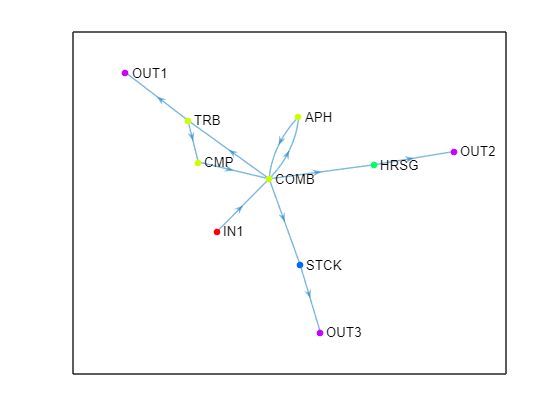

sc=cDigraphAnalysis(tfp,names);
sc.plotGraph;

### Get the Kernel Graph

disp(showGroupsTable(sc))

      Name      Component
    ________    _________

    {'IN1' }    {'IN'  } 
    {'COMB'}    {'SC1' } 
    {'CMP' }    {'SC1' } 
    {'TRB' }    {'SC1' } 
    {'APH' }    {'SC1' } 
    {'HRSG'}    {'HRSG'} 
    {'STCK'}    {'STCK'} 
    {'OUT1'}    {'OUT' } 
    {'OUT2'}    {'OUT' } 
    {'OUT3'}    {'OUT' } 



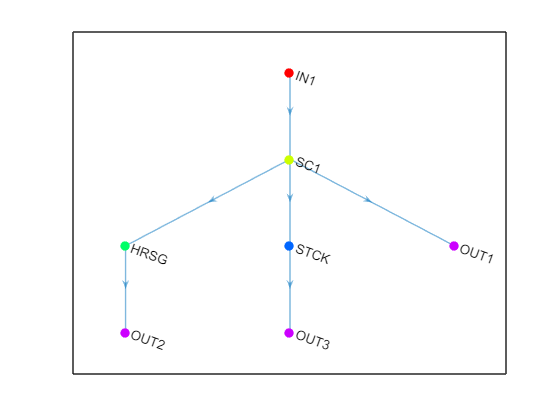

sc.plotKernelGraph;

### Print Kernel Table FP

fmt=data.FormatData;
[kG,knodes]=sc.getKernelTable;
tbl=fmt.getTableFP('tfp',kG,knodes);
tbl.setDescription('Kernel FP Table');
tbl.setStudyCase(res.StudyCase);
printTable(tbl)


Kernel FP Table (MW) - REF

 Key             SC1       HRSG       STCK        ENV      Total
—————————————————————————————————————————————————————————————————
 SC1           0.000     12.662      2.122     30.000     44.784
 HRSG          0.000      0.000      0.000      9.303      9.303
 STCK          0.000      0.000      0.000      2.122      2.122
 ENV          72.465      0.000      0.000      0.000     72.465
—————————————————————————————————————————————————————————————————
 Total        72.465     12.662      2.122     41.425           



### Non-SSR Digraph Example

A=[0 1 0 0 0 0 0;
   0 0 1 0 0 0 0; 
   1 0 0 0 0 0 0; 
   0 0 1 0 0 1 0; 
   0 0 0 1 0 0 0; 
   0 0 0 0 1 0 1; 
   1 0 0 0 0 0 0];
sc=cDigraphAnalysis(A);
[res,src,out]=sc.isProductive;
fprintf('Productive Graph: %s',mat2str(res));

Productive Graph: false

if ~isempty(src)
fdisplay(src,'%3d','Nodes Non-Reached from IN');end

Nodes Non-Reached from IN
  4  5  6



if ~isempty(out)
fdisplay(out','%3d','Nodes does not reach OUT');end

Nodes does not reach OUT
  1  2  3



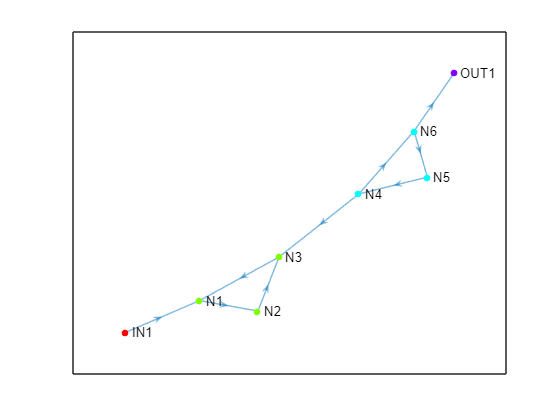

sc.plotGraph;

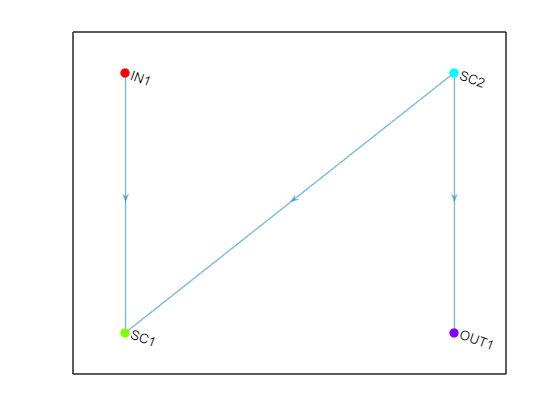

sc.plotKernelGraph;

### Productive Graph Example

A=[0 1 0 0 0 0 0; 
   0 0 1 0 0 0 0; 
   1 0 0 1 0 0 0; 
   0 0 0 0 0 1 0; 
   0 0 0 1 0 0 0; 
   0 0 0 0 1 0 1; 
   1 0 0 0 0 0 0];
sc=cDigraphAnalysis(A);
fprintf('Productive Graph: %s',mat2str(sc.isProductive));

Productive Graph: true

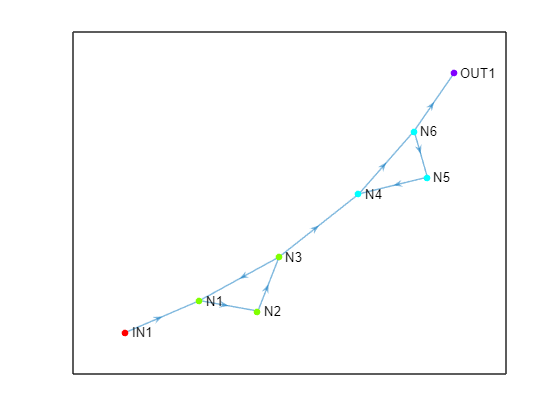

sc.plotGraph;

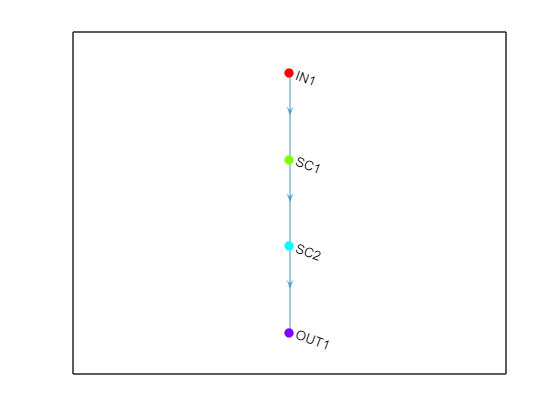

sc.plotKernelGraph;